# Timing Recovery Method Exploration

## Simulation Setup

Fs = 4 * 10^6; % Sampling rate
Tmax = 0.1; % Max time
N = Tmax * Fs; % Number of samples
B = 350 * 10^3; % Bandwidth
% Use these guys for plotting
t = linspace(0, Tmax-1/Fs, N); % Time variable
f = linspace(-Fs/2,Fs/2, N); % Frequency variable

Rs = 50 * 10^3; % Symbol rate in symbols/sec (baud)
Ns = Rs * Tmax; % Number of symbols to send
sps = Fs / Rs; % Number of samples per symbol
Ts = 1 / Rs;

fc = 1 * 10^6; % Carrier frequency in Hz

beta = 0.5; % RRC rolloff factor
span = 5; % number of symbols for length of filter impulse response
srrc = rcosdesign(beta, span, sps, 'sqrt'); % srrc transmitter/receiver impulse response

## Transmitter

%% Stream of Bits (binary message)

bits = [0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1,...
       1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0,...
       0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1,...
       0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0,...
       0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 0 1 0 0 0 0 0 0 1,...
       1 0 1 0 0 1 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 0 0 1 1 0 0 0 1 1 0 1 1 0,...
       1 1 1 1 0 1 1 0 1 1 0 1 0 1 1 1 0 0 0 0 0 1 1 0 1 1 0 0 0 1 1 0 0 1,...
       0 1 0 1 1 1 0 1 0 0 0 1 1 0 0 1 0 1];

%% Convert to BPSK Symbols

symbols = bits;
symbols(symbols == 0) = -1;

%% Append Packet Header

key = [1 1 1 -1 -1 -1 1 -1 -1 1 1 -1 1 -1 1];
header = repmat(key, 1, 3);

packet = [header symbols];
packet_length = length(packet)

packet_length = 301

%% Optionally pad by a random integer-number of symbols

m = zeros(1, abs(round(normrnd(50, 10))));
packet = [m packet];

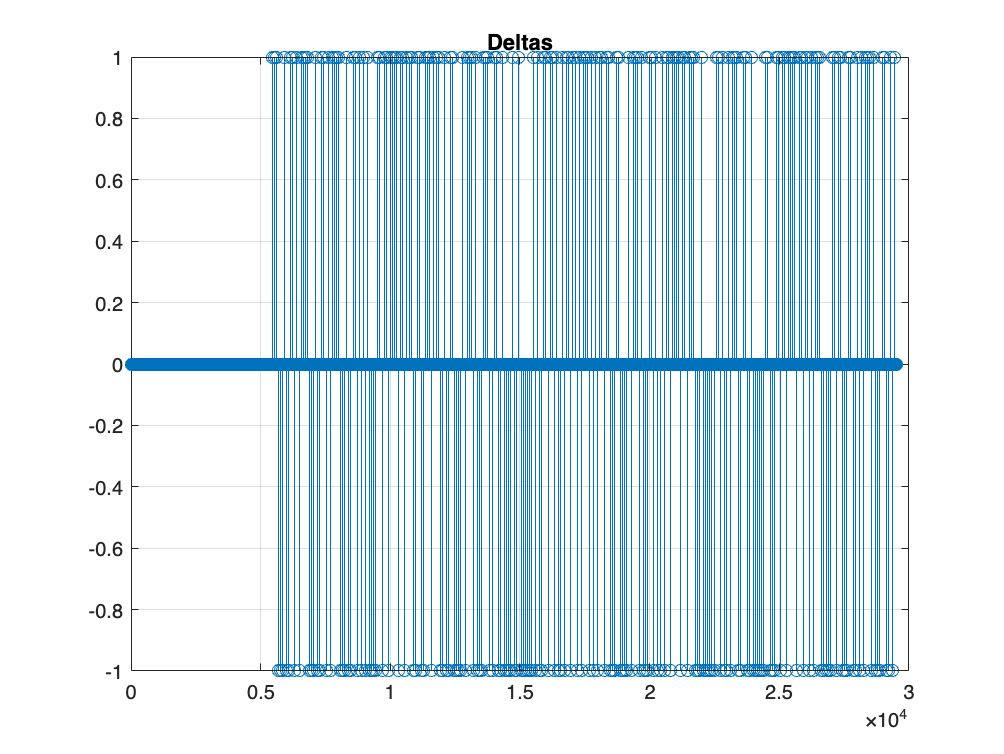

%% Upsample symbols by sps to form a delta train

deltas = upsample(packet, sps);

stem(deltas)
title("Deltas")

figure

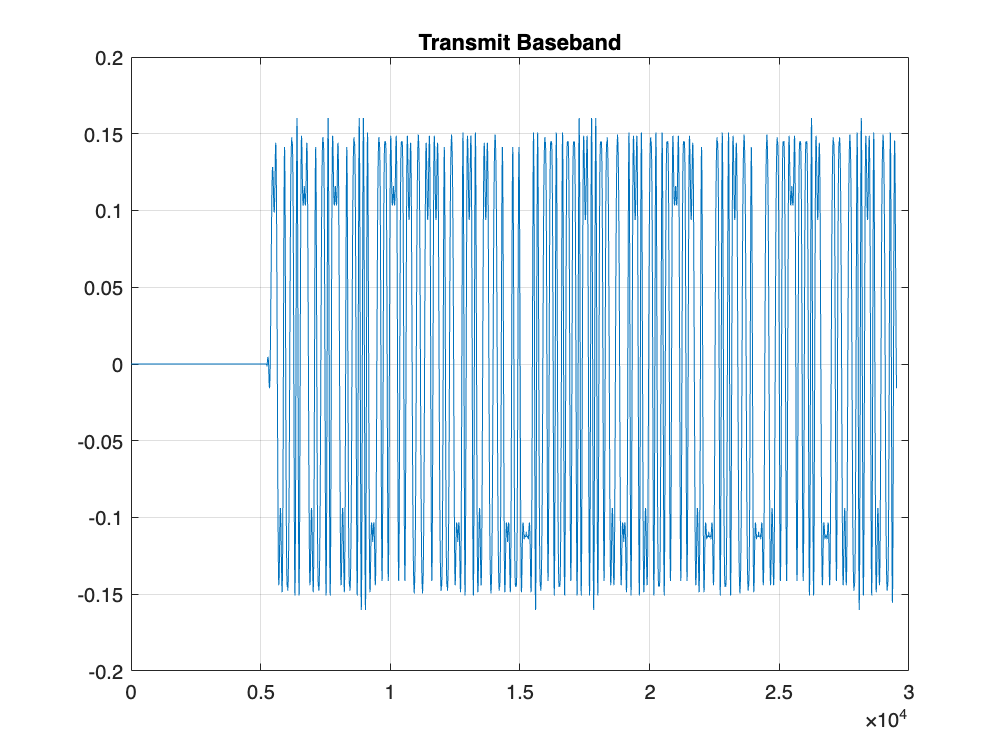

%% Apply Transmitter SRRC

transmit_bb = upfirdn(deltas, srrc, 1, 1); % convolve deltas with srrc
transmit_bb = transmit_bb(length(srrc)/2+0.5:end-length(srrc)/2+0.5); % alignment with deltas

plot(transmit_bb)
title("Transmit Baseband")

figure

#### Tx-Applied Symbol-Fractional Timing Offset

This is a key block differing from previous iterations of WRAP software.

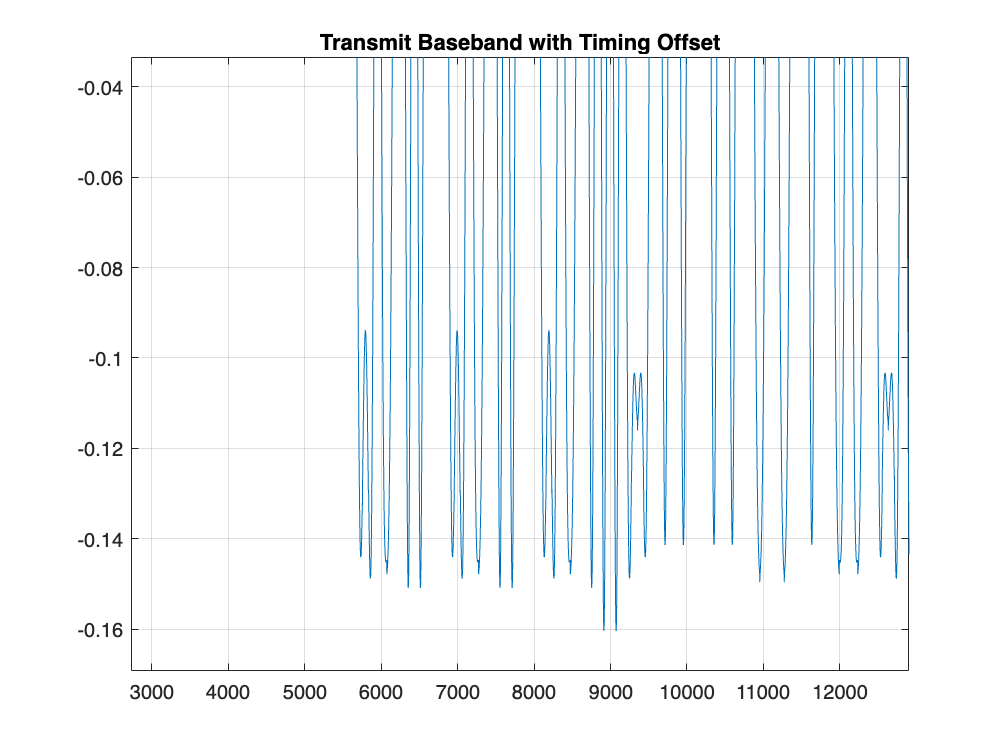

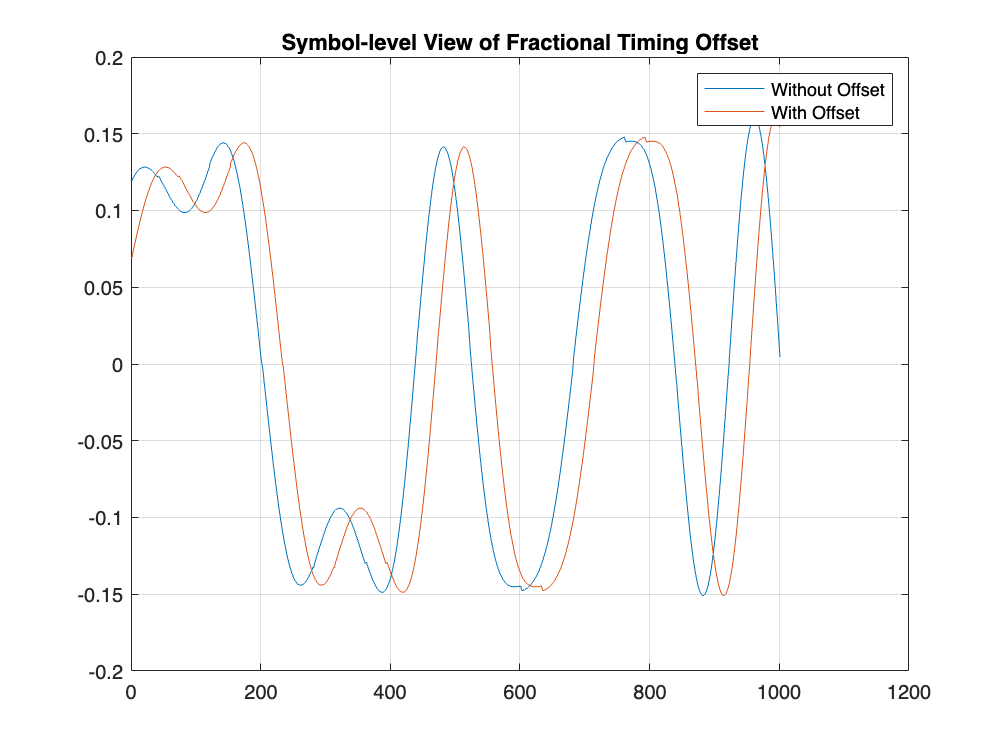

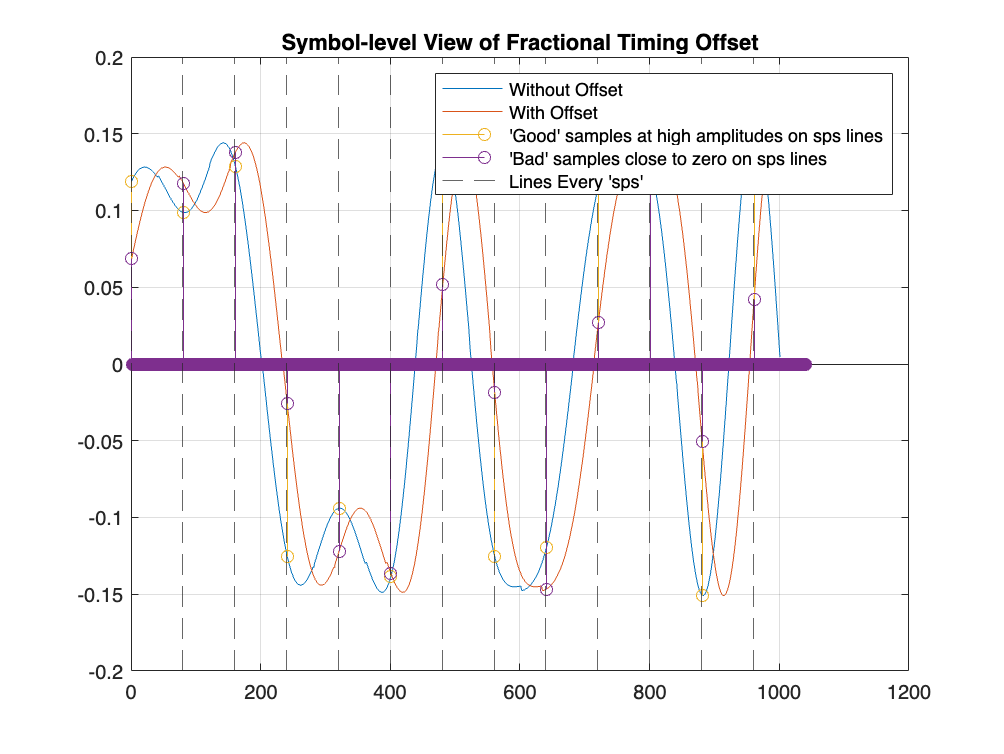

%% Symbol-Fractional Timing Offset
timing_offset_frac = 0.4; % 0 < tau < 1

% A timing offset of 0.4 to 0.6 symbols is worst-case
% for timing recovery performance

stored_transmit_bb = transmit_bb; % store before applying timing offset

timing_offset_samps = round(timing_offset_frac * sps);
timing_offset_time = timing_offset_frac * Ts;
transmit_bb = [zeros(1, timing_offset_samps) transmit_bb];

% Plot Timing Offset
timing_offset_plots(transmit_bb, stored_transmit_bb, sps, m, 1000);

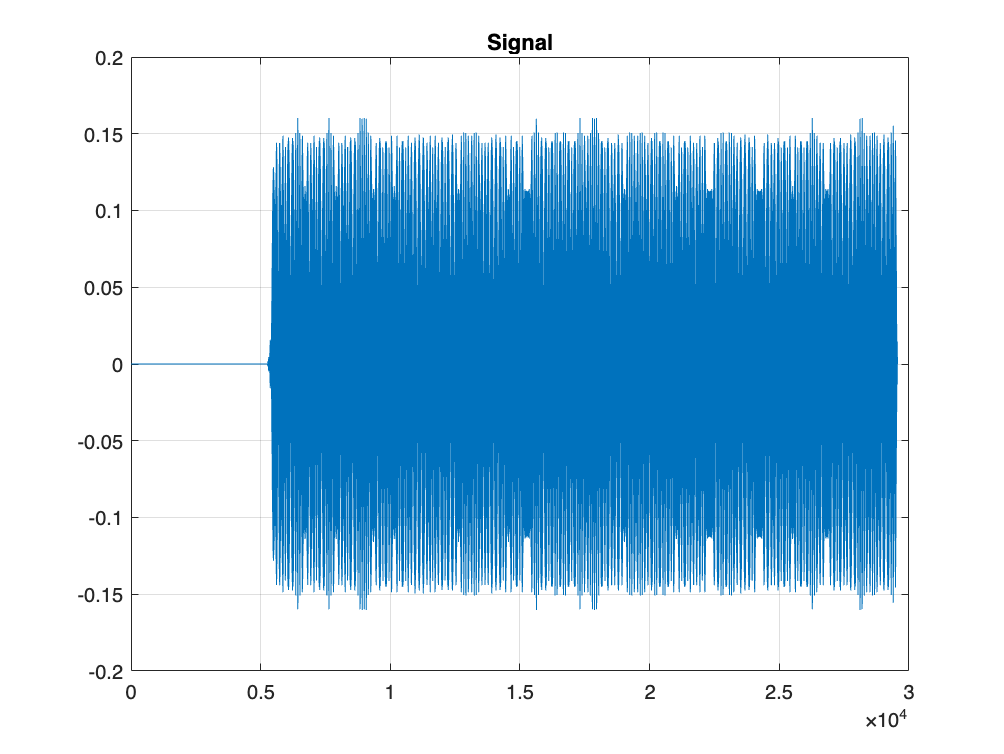

%% Carrier Modulation

signal = modulate_carrier(transmit_bb, fc, t);


% Mixes the signal with a sinusoid at the
% carrier frequency fc

## Channel Impairments

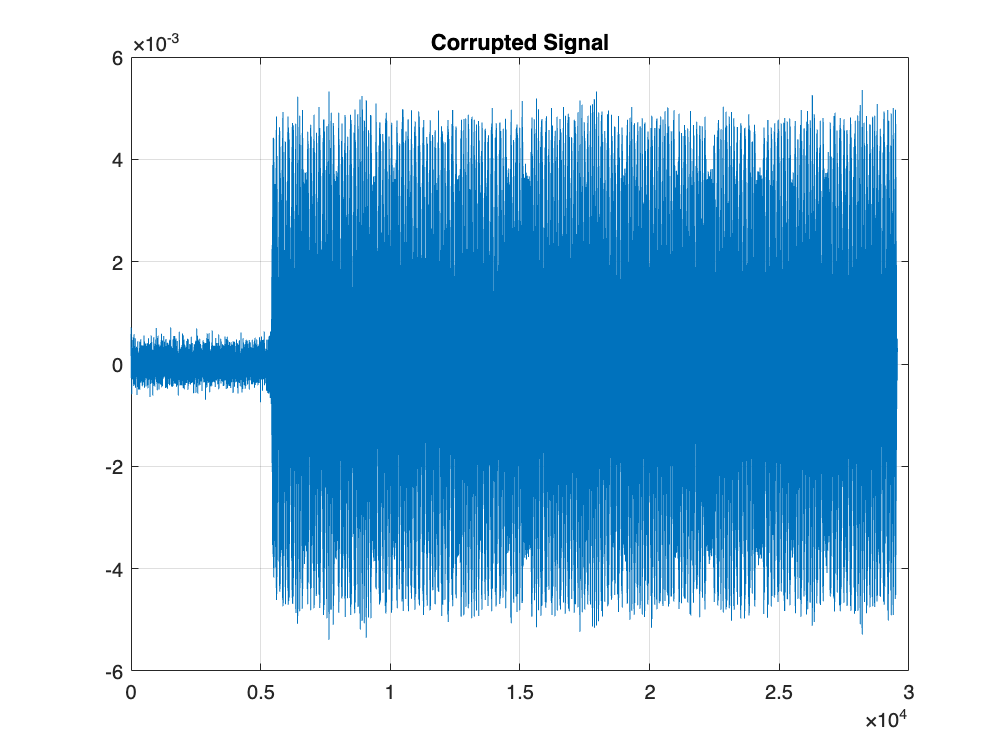

[signal, phase_offset] = add_channel_impairments(signal, B, fc, Fs, 0.0002);


% Bandlimited channel filter
% Non-ideal phase shift
% AWGN

## Rx-Applied Carrier Frequency Offset

frequency_variation = 10 * 10^3;

fr = fc + frequency_variation;

% Rx initially guesses a carrier frequency
% of fr, meaning a CFO of frequency_variation

## Apply "Fake" AGC (Automatic Gain Control)

signal = normalize(signal); % approximation of AGC behavior

% Signal normalization is necessary for stability
% of PID tuning constants

## Joint Demodulation & Carrier Recovery with Costas Loop

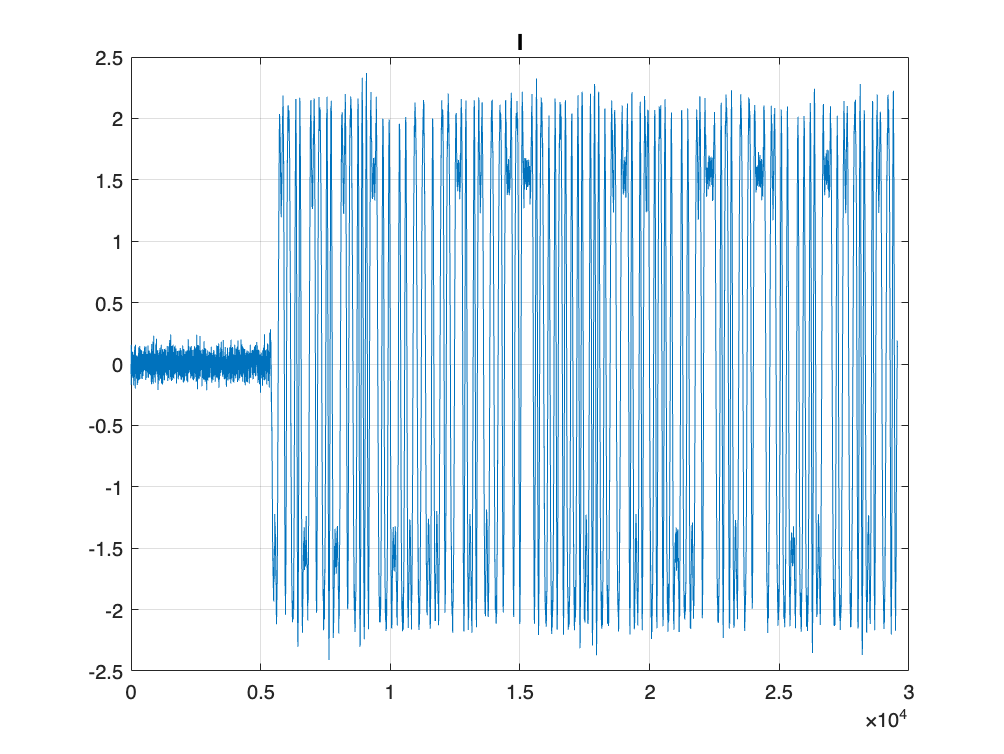

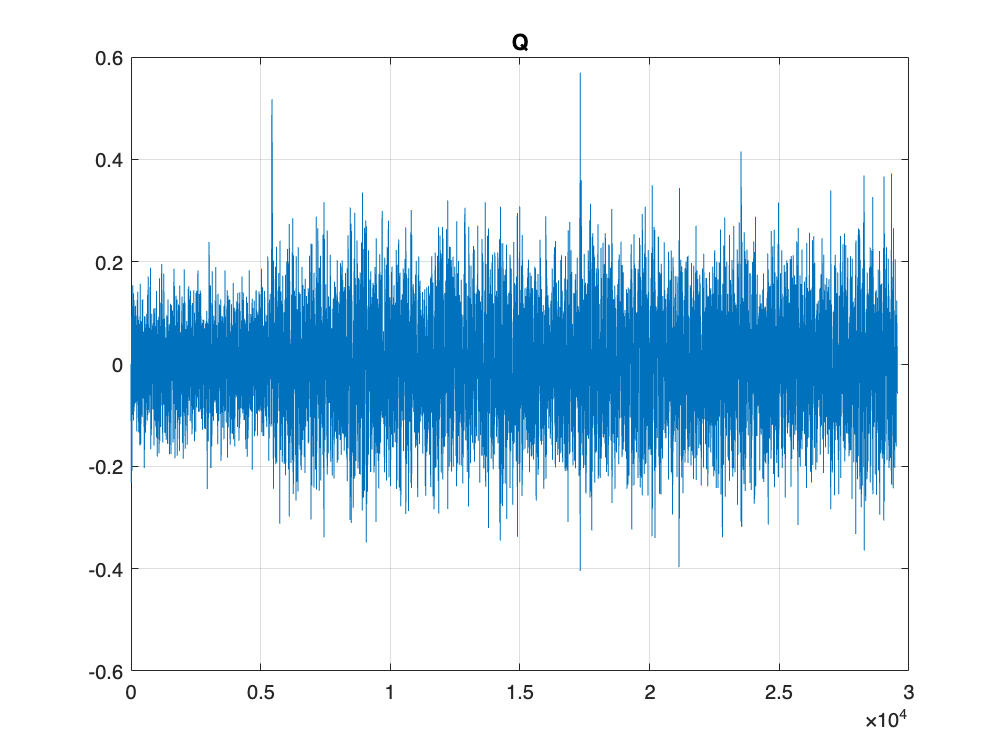

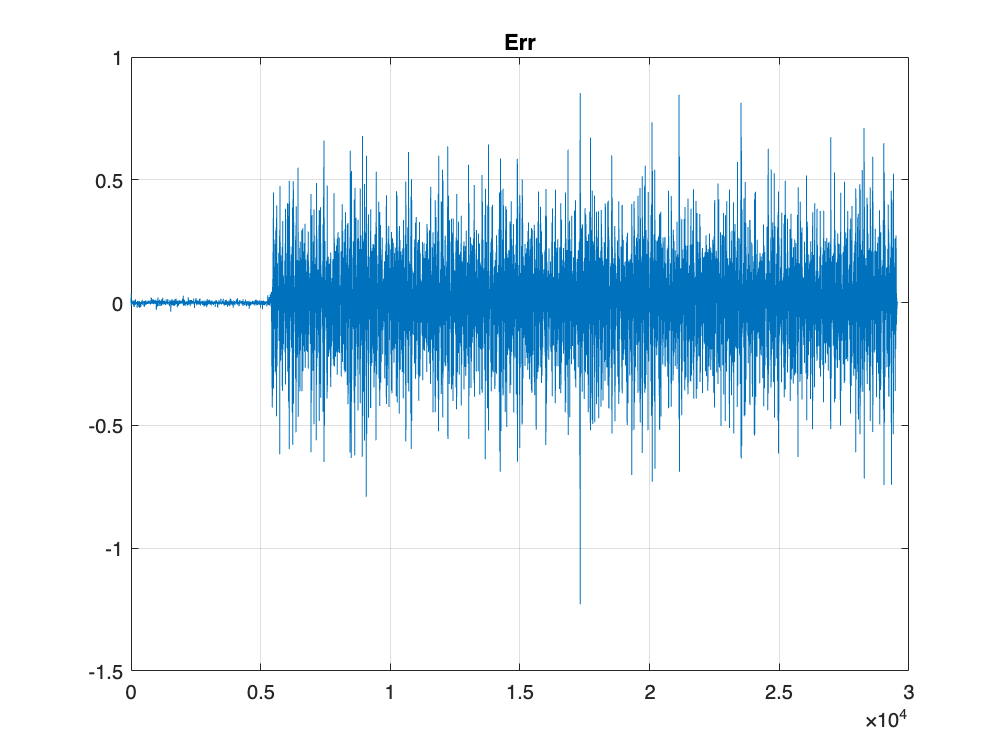

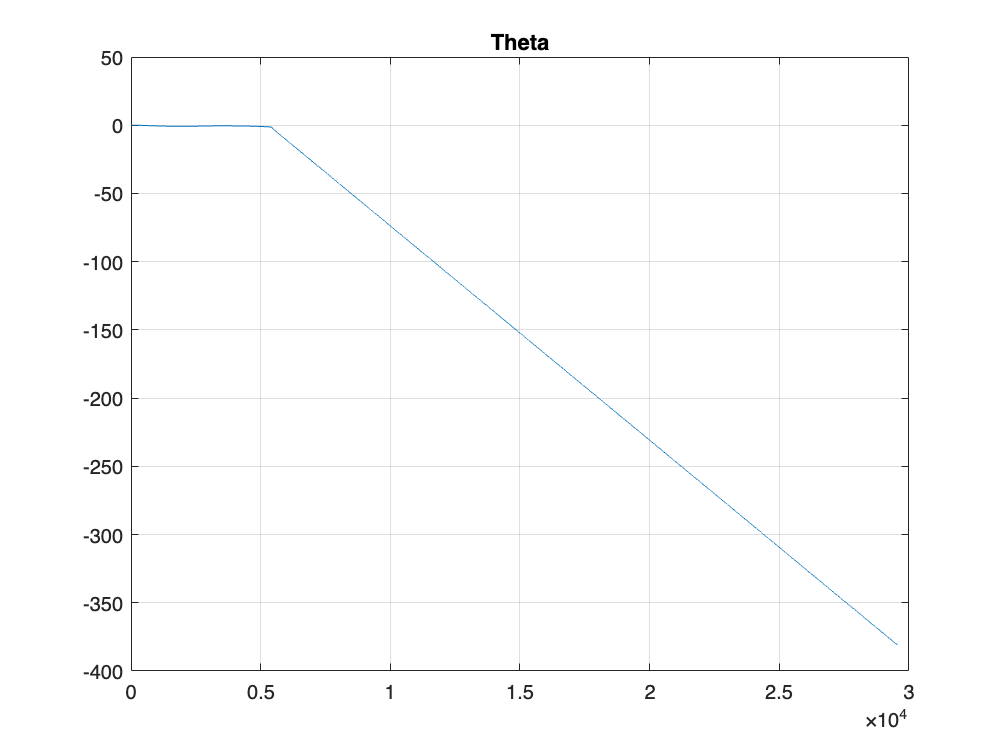

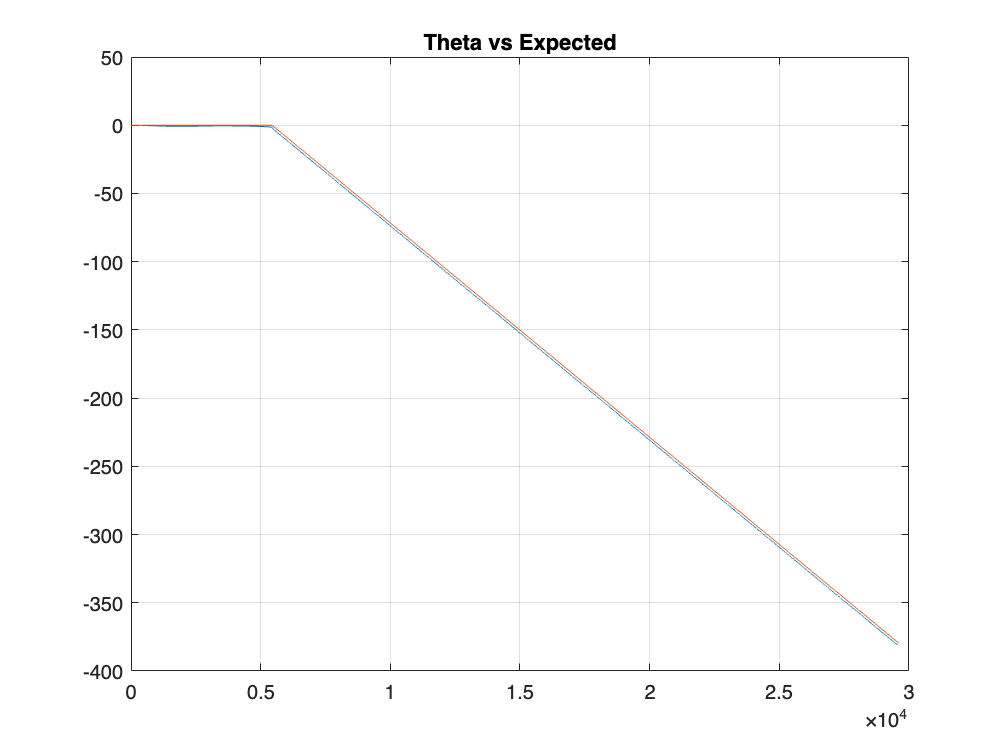

% PID Tuning Constants
Kp = 0.1;
Ki = 0.002;
Kd = 0;

% Apply Costas Loop
[I, Q, theta, err] = carrier_recovery_pll(signal, fr, Fs, t, Kp, Ki, Kd);
% Costas Loop Plotting
costas_loop_plots(I, Q, theta, err, fc, frequency_variation, sps, m, phase_offset, 1, length(I));

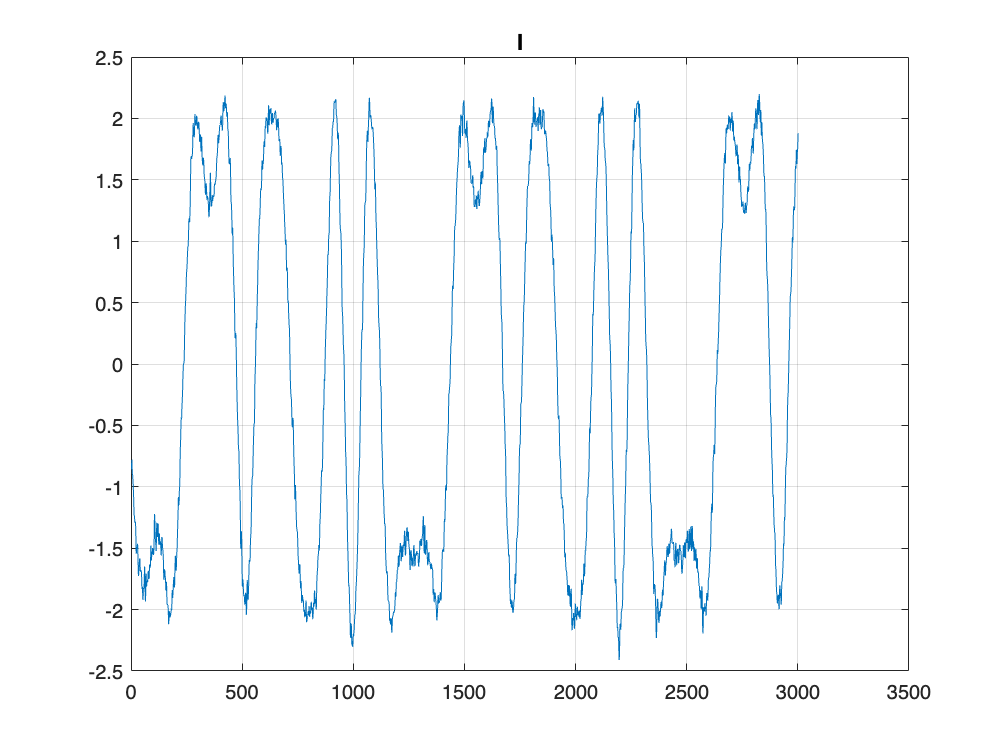

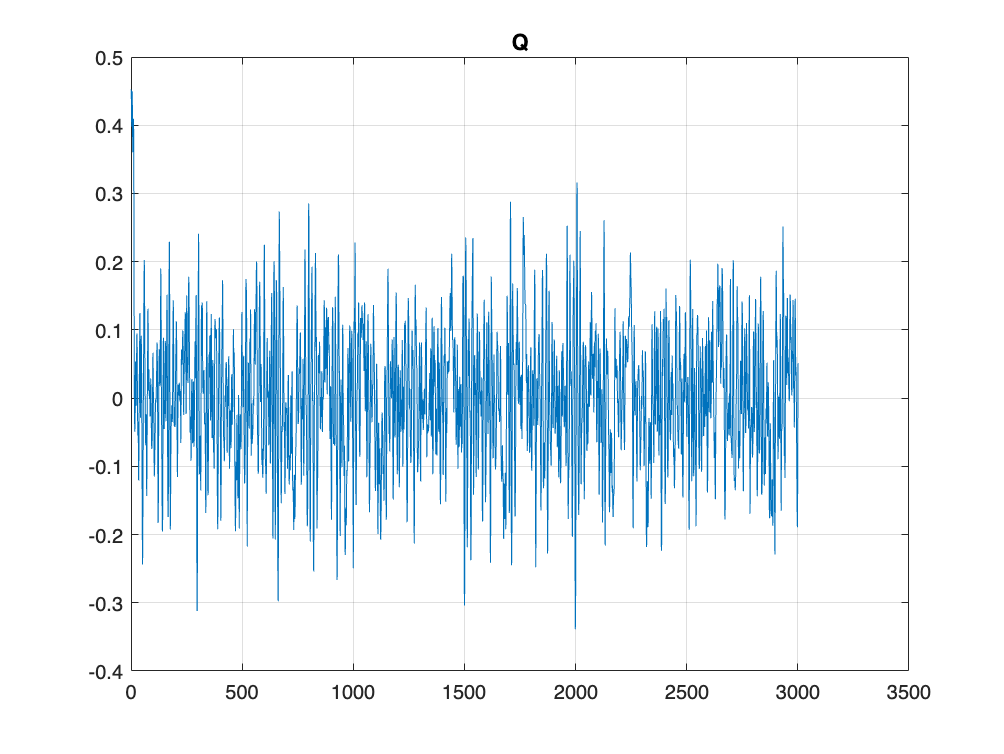

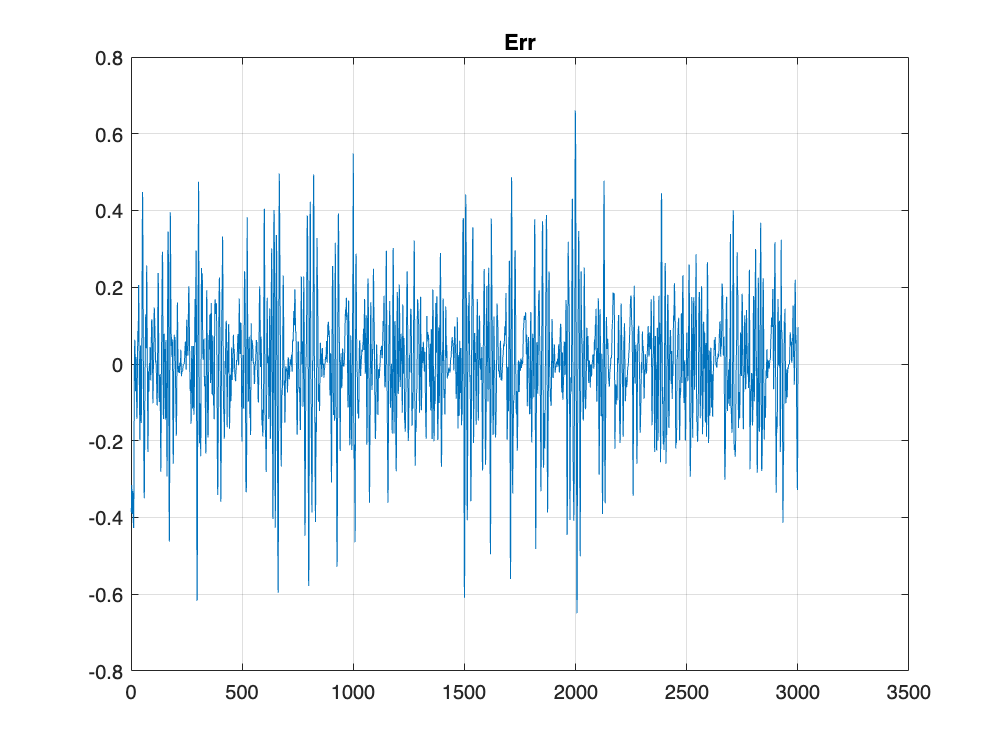

costas_loop_plots(I, Q, theta, err, fc, frequency_variation, sps, m, phase_offset, length(m)*sps, length(m)*sps+3000);

%% Apply Receiver SRRC

receive_bb = I + 1j * Q;

received_samples = upfirdn(receive_bb, srrc, 1, 1); % convolve deltas with srrc
received_samples = received_samples(length(srrc)/2+0.5:end-length(srrc)/2+0.5);

## Why Do We Need Timing Recovery?

Carrier Recovery --> de-rotates our constellation, turns it from a circle into a straight line

Timing Recovery --> downsamples our constellation, turns it from a solid line into just two points

Ideal BPSK symbol constellation has just two point clusters!

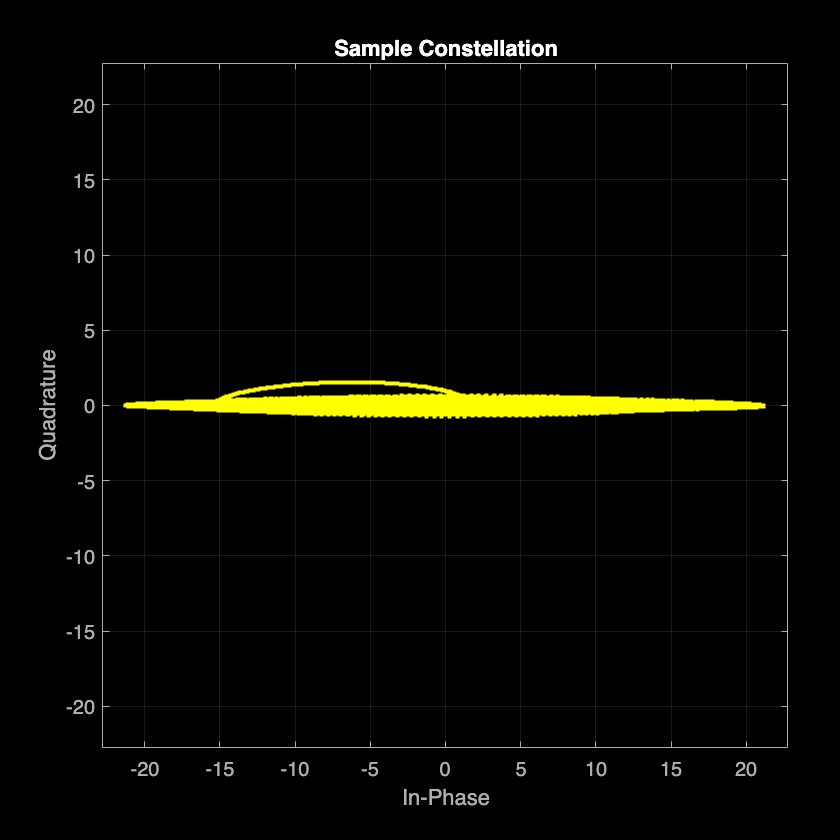

% We need timing recovery to pick out the 'correct' samples
% of the sample constellation to be our symbol-decision points.
% We want the eye diagram to be maximally open (--> maximal
% distance from the decision boundary), so we *roughly* choose
% samples around either distant endpoint

scatterplot(received_samples)
title("Sample Constellation")

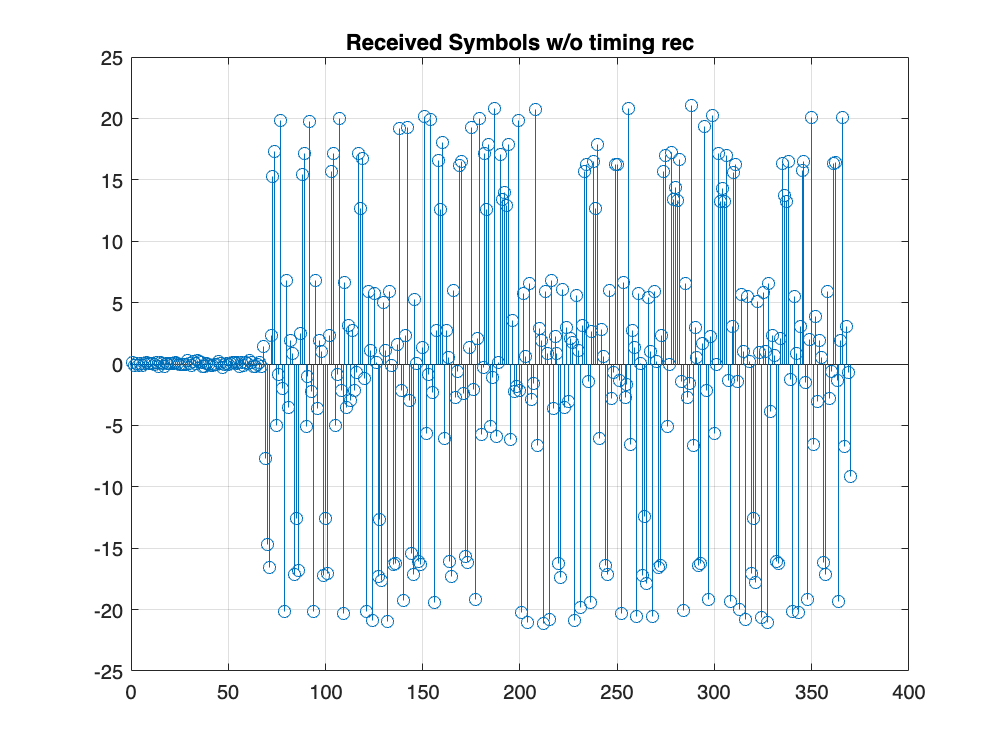

figure

% This is what we'd have without timing recovery
% aka just drawing naively every sps samples
received_symbols = received_samples(1:sps:end);
stem(real(received_symbols))
title("Received Symbols w/o timing rec")

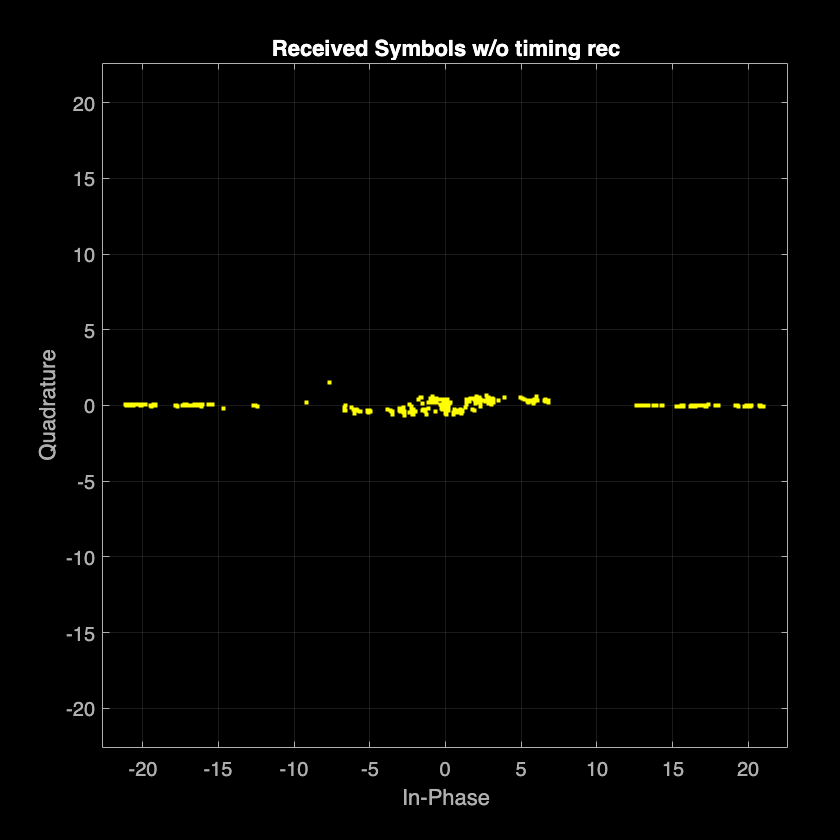

figure

scatterplot(received_symbols)
title("Received Symbols w/o timing rec")

figure

## Re-apply "Fake" AGC

x = normalize(real(received_samples));

% Signal normalization is necessary for stability
% of PID tuning constants

% Technically not needed, but a 2nd 'AGC' is
% convenient for running simulations

## Rx-Applied Samples-per-symbol Offset

% Apply SPS offset at the receiver -- can be fractional
sps_offset = 2.2;
sps = 80 + sps_offset;

% Timing offset is comparable to carrier phase offset
% Sample-per-symbol offset is comparable to carrier frequency offset

## Timing Recovery with Different Methods

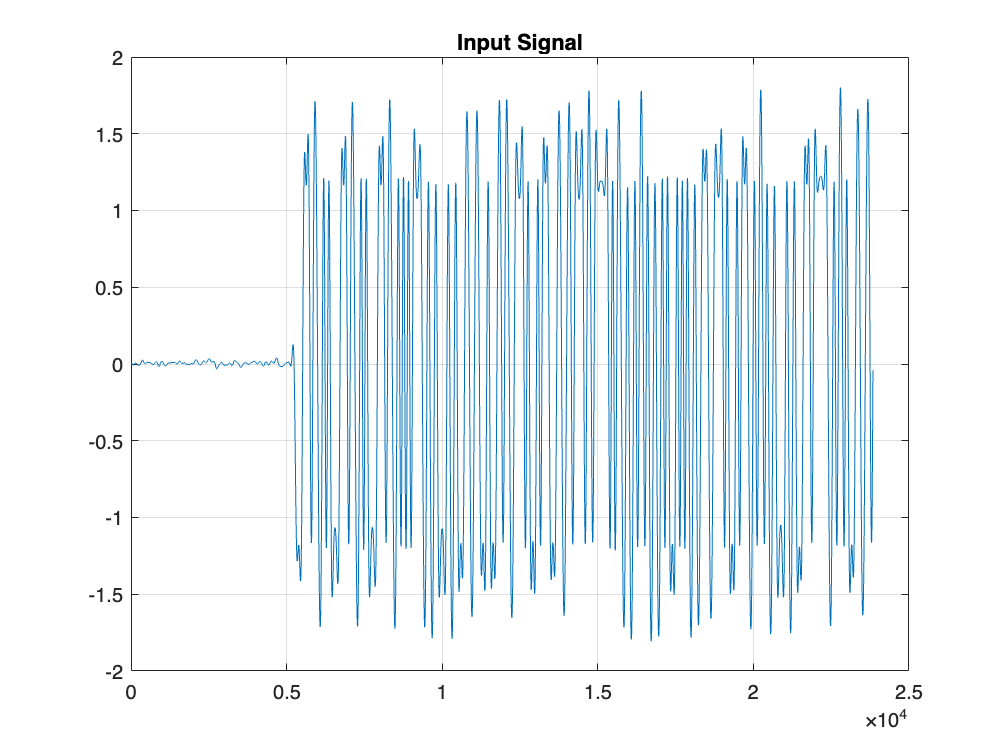

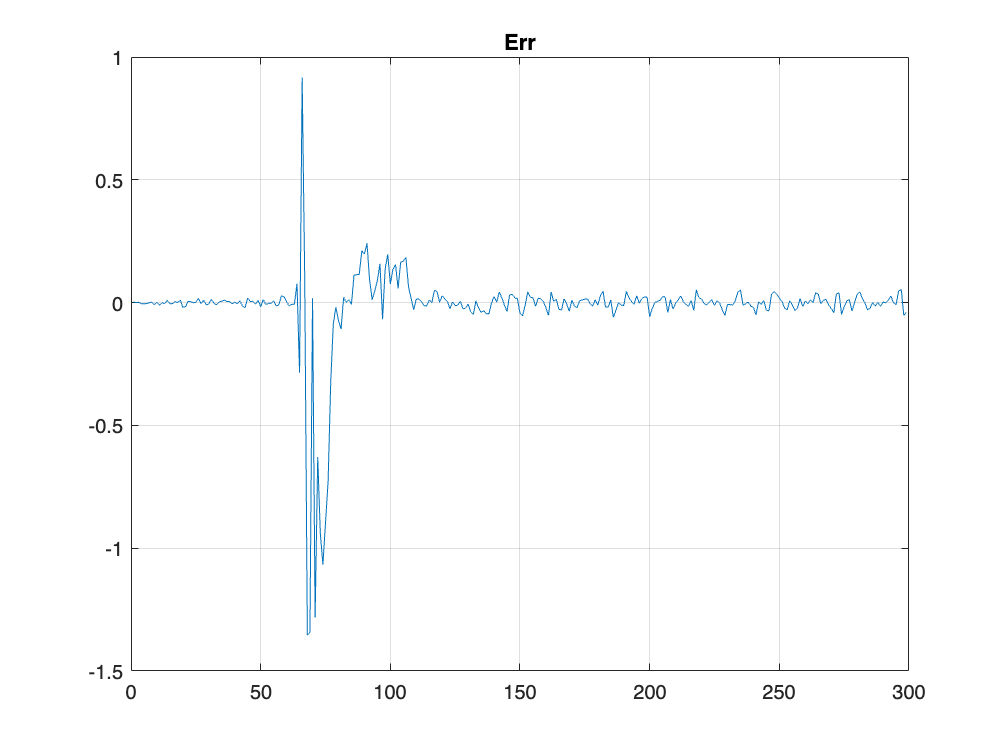

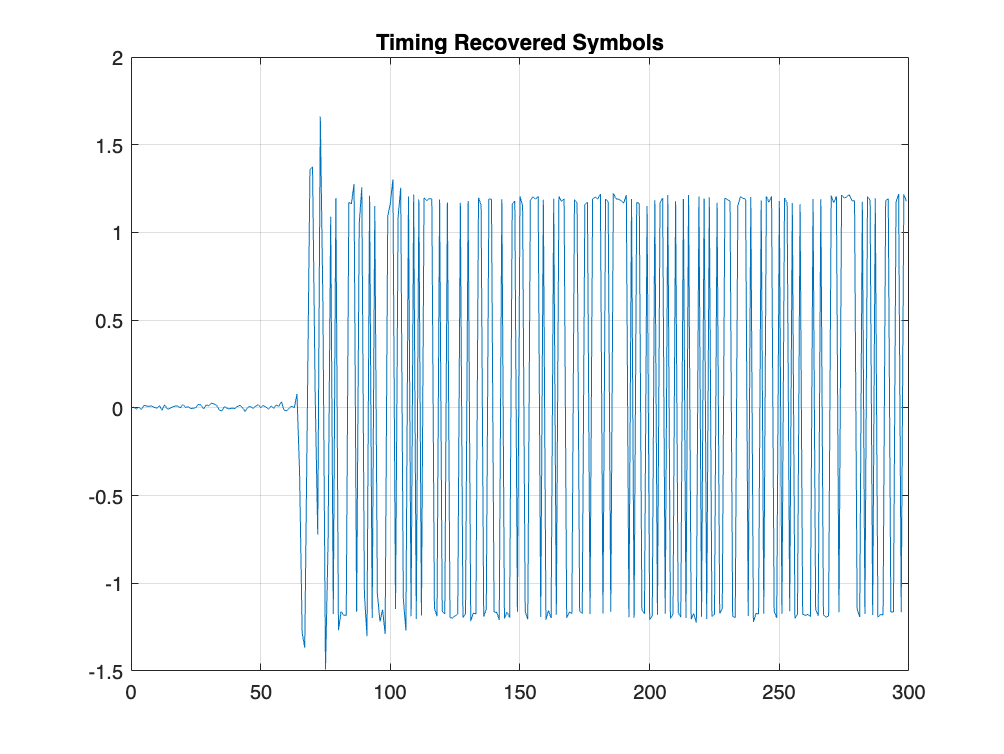

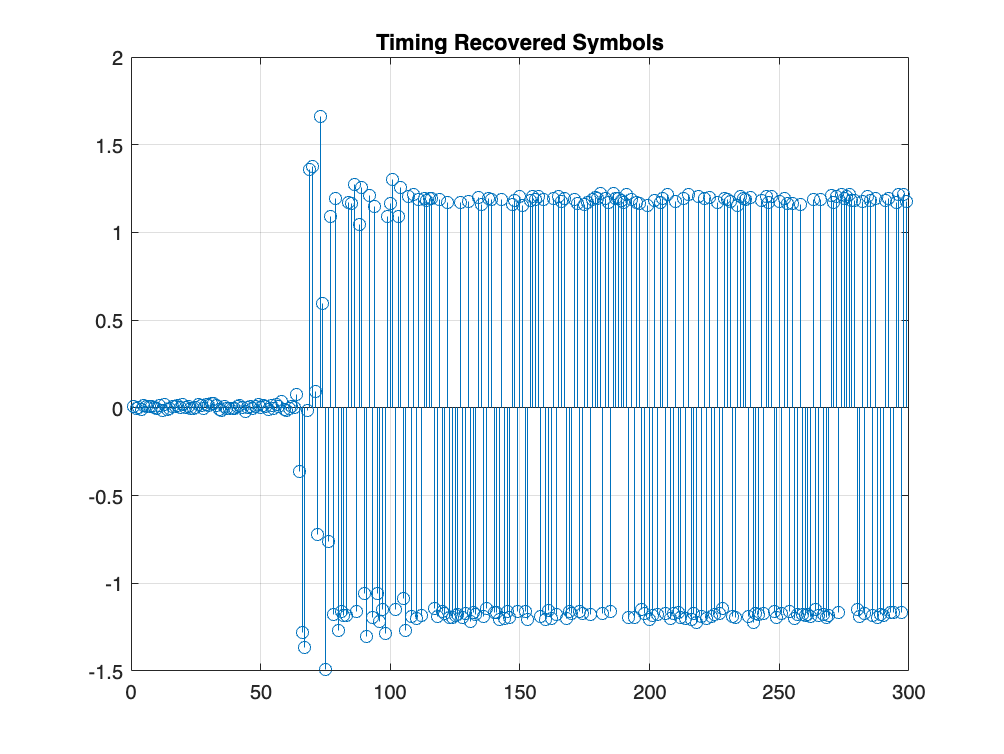

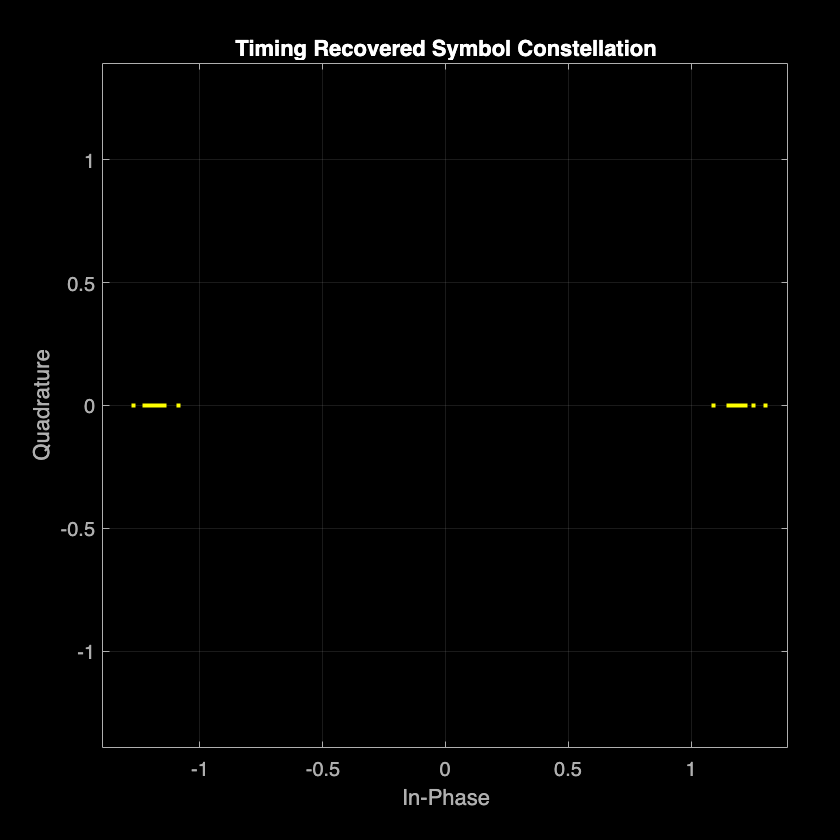

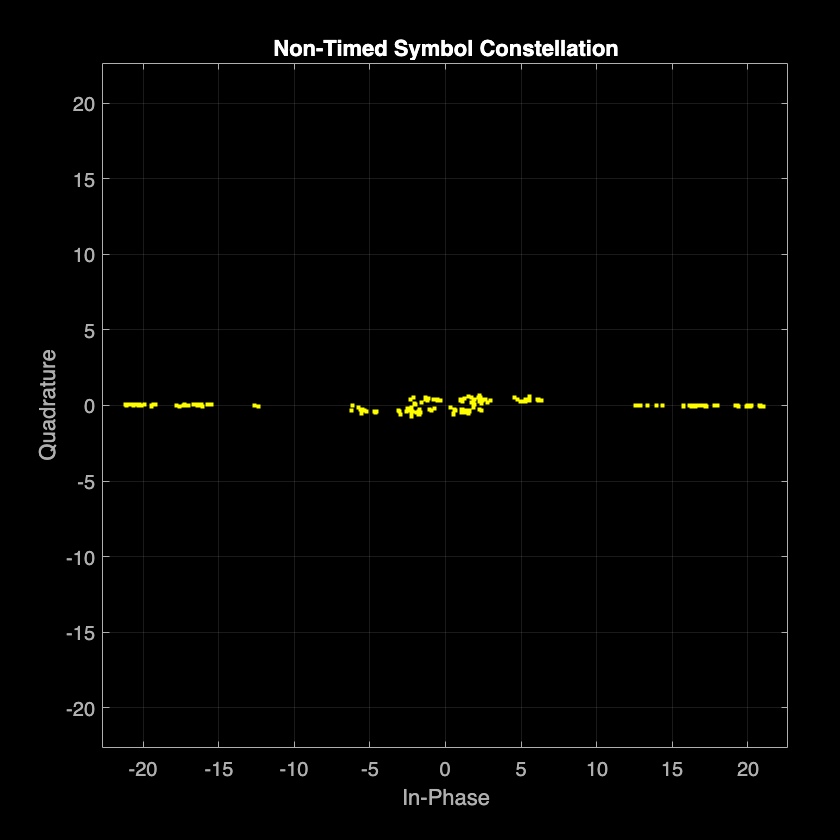

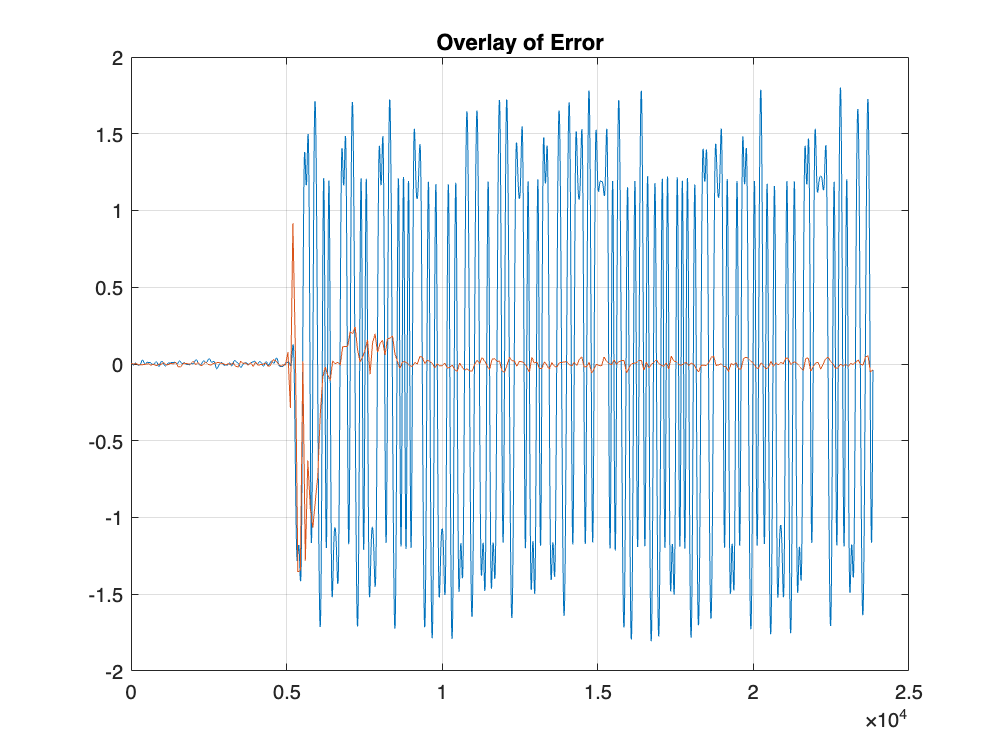

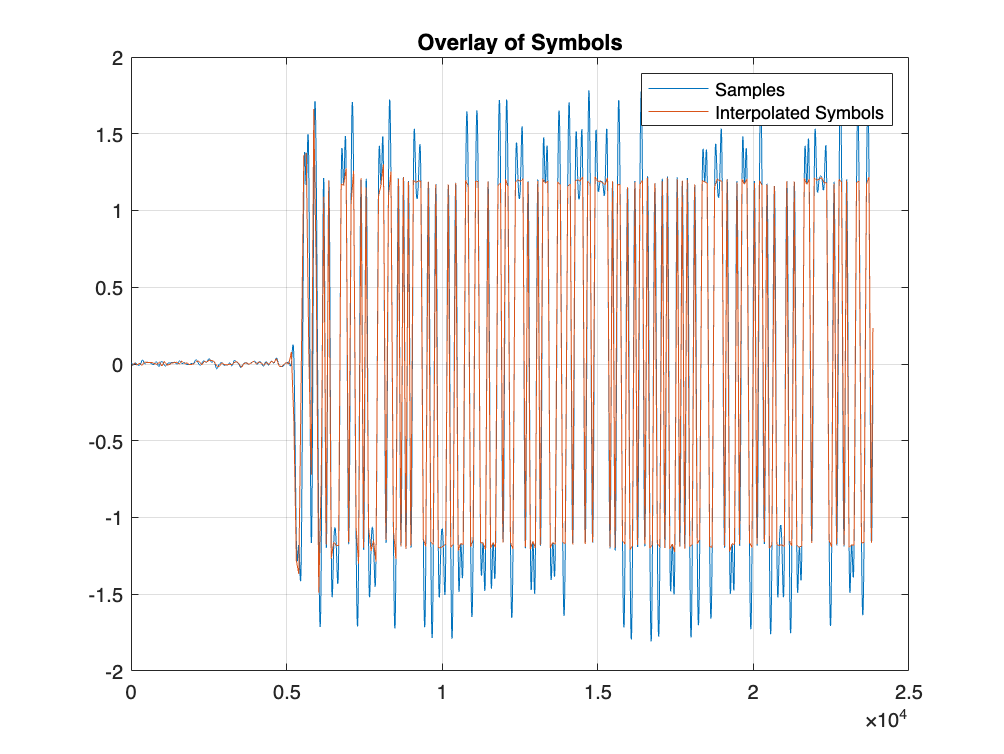

% PID Tuning Constants
Kp = 4.5; % observe how Kp causes faster settling w/o oscillation but increases self-noise effect
Ki = 0.4; % observe how Ki smooths the oscillations before settling to a constant offset (but eventually goes unstable)
Kd = 0.0; % observe how Kd increases high frequency noise in the lock

% Apply Timing Recovery
[symbs, tau, err] = timing_recovery_pll(x, sps, Kp, Ki, Kd, "Mueller-Muller");
% Timing Recovery Plots
% Full picture:
timing_recovery_plots(timing_offset_samps, received_samples, x, sps, sps_offset, m, symbs, tau, err, 2, 300, 100, 300);

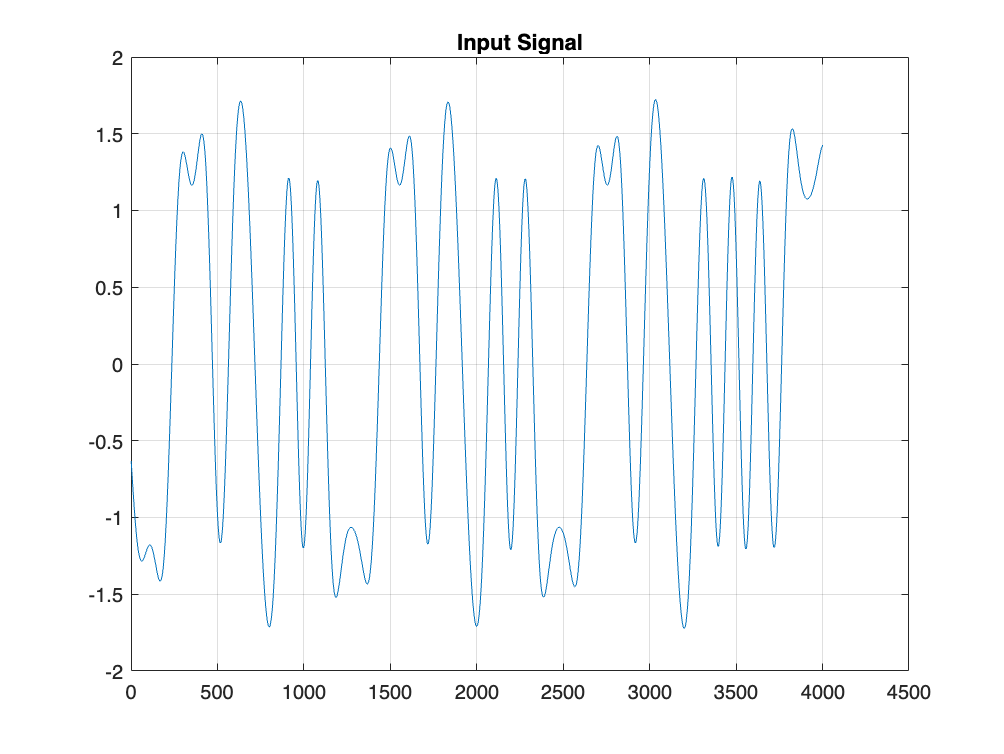

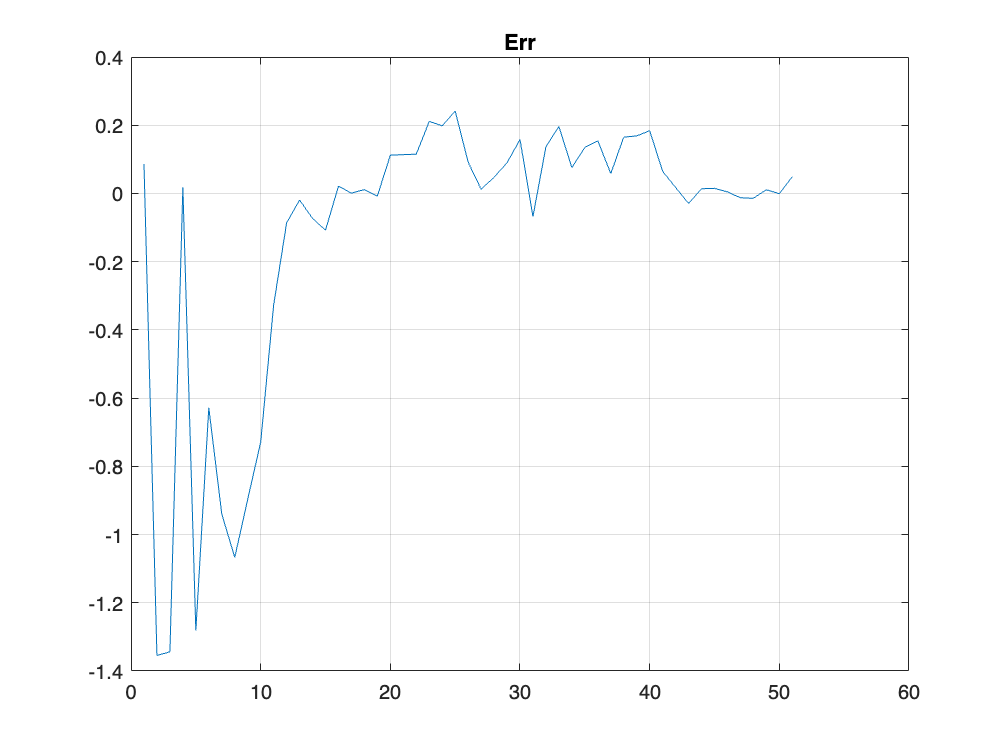

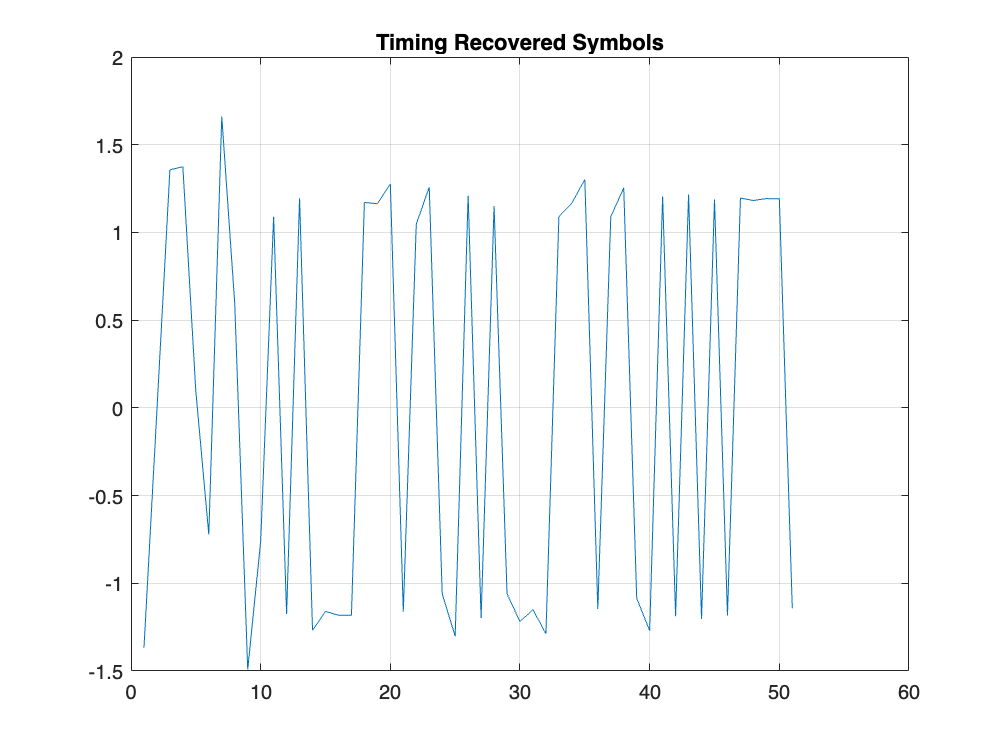

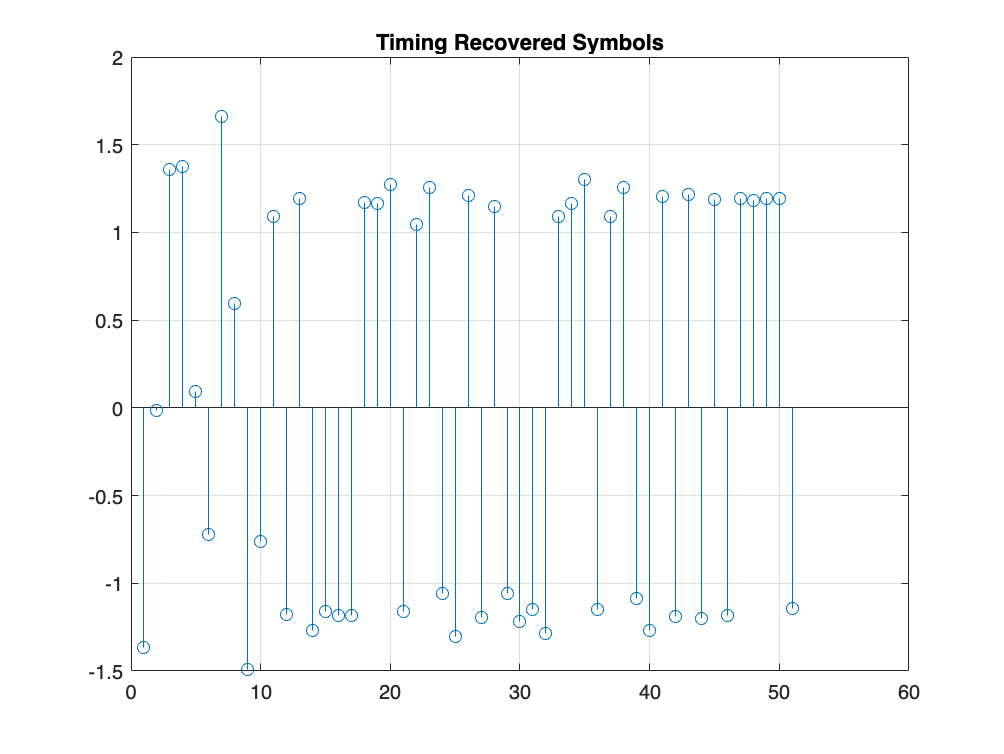

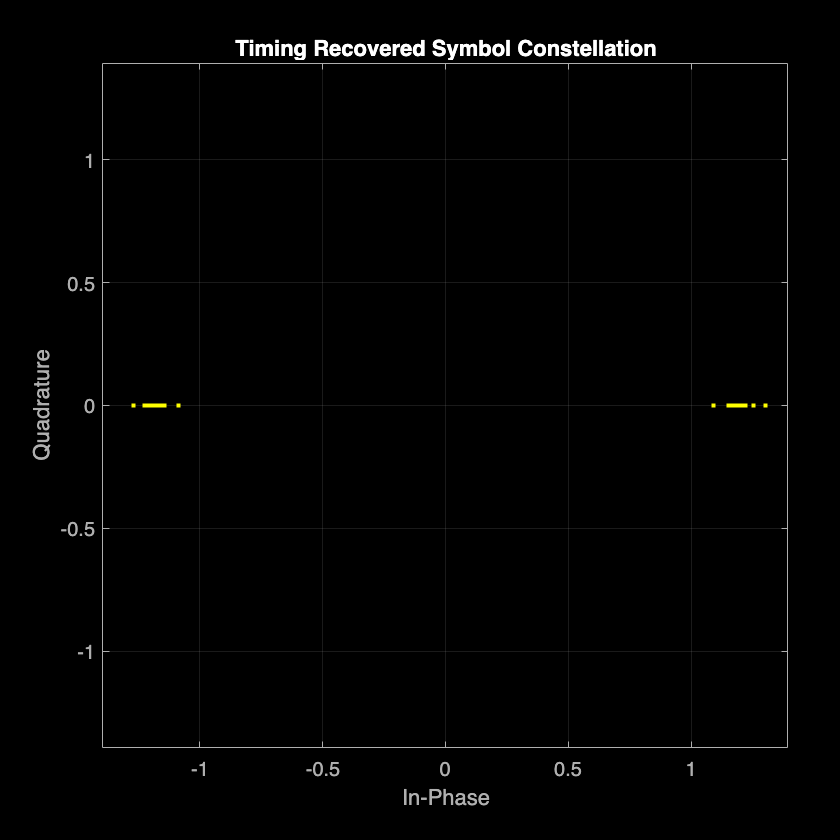

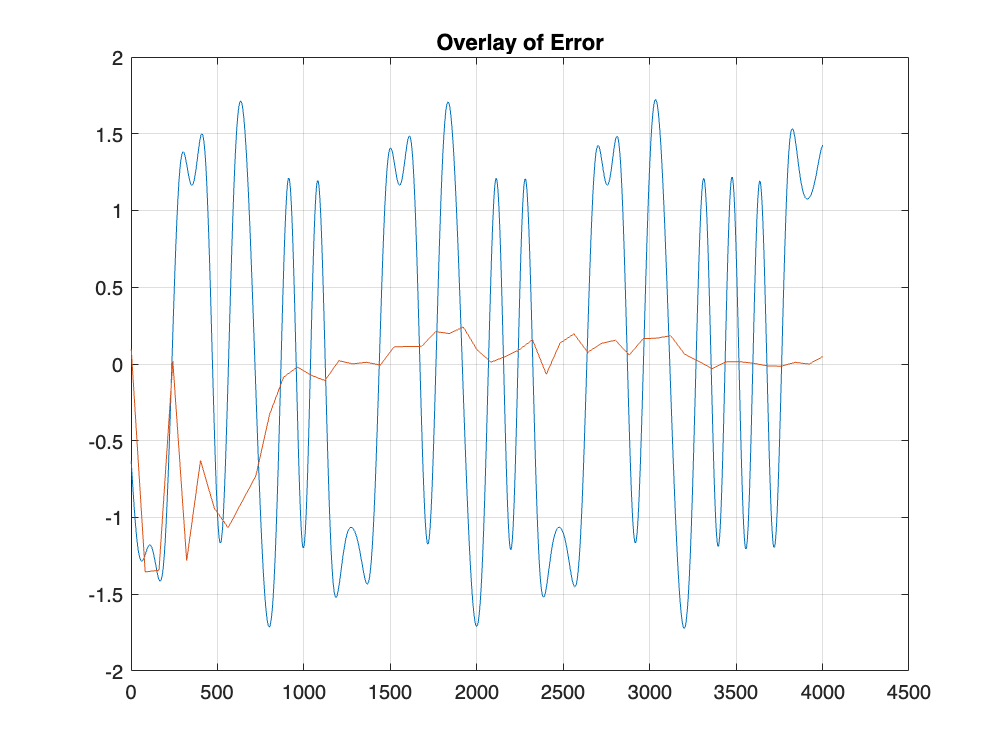

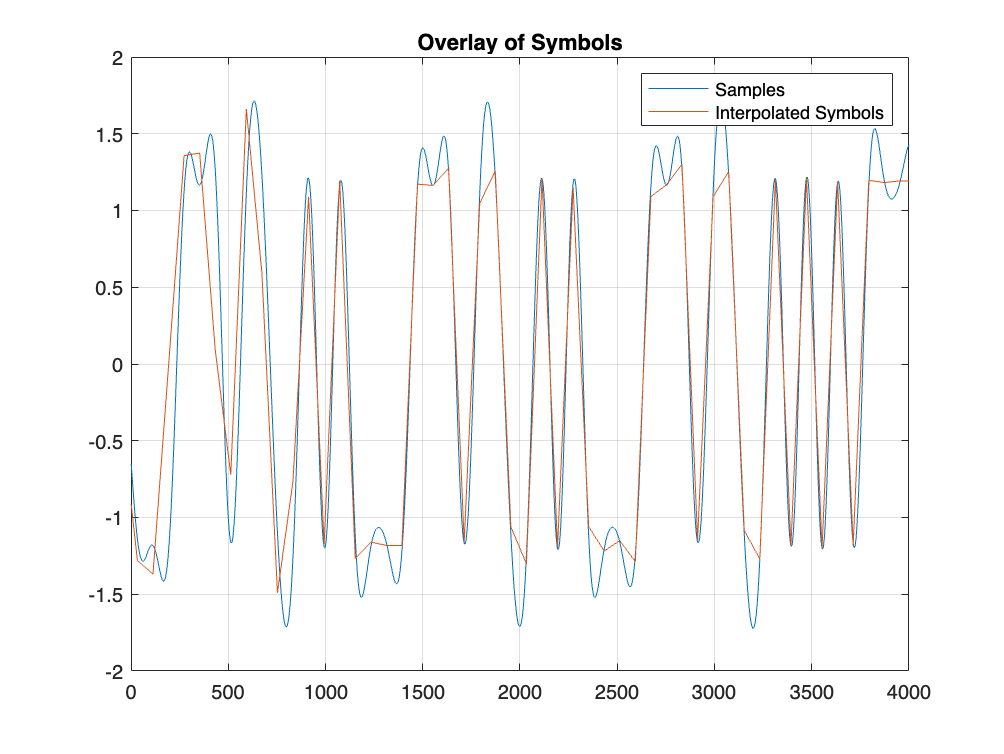

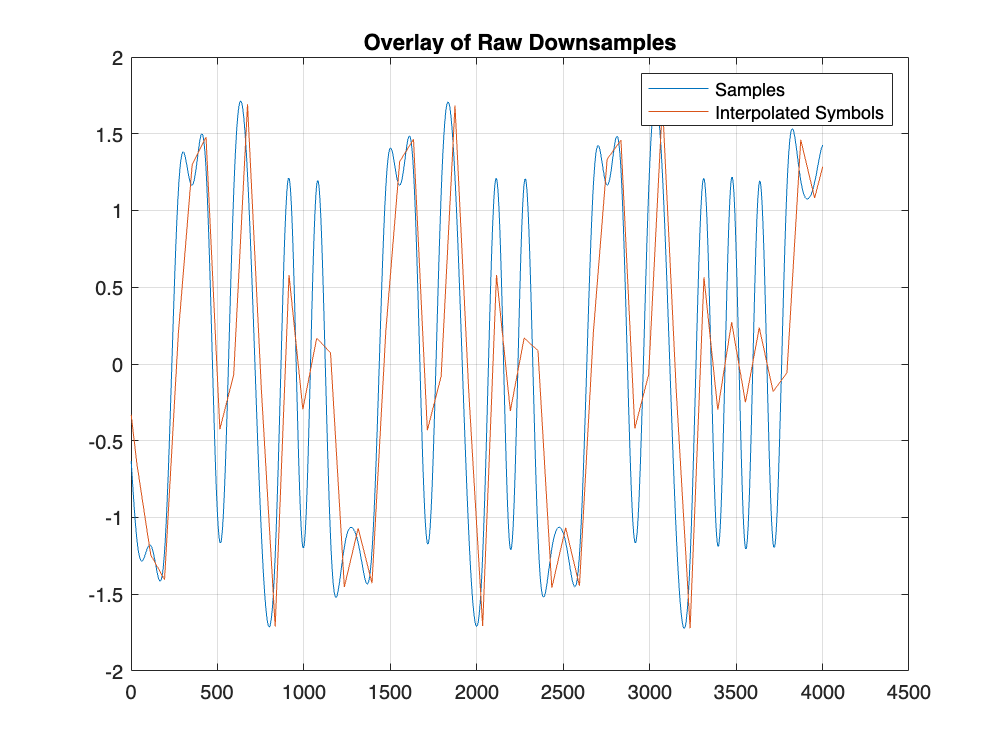

% Zoom-in on initial locking:
timing_recovery_plots(timing_offset_samps, received_samples, x, sps, sps_offset, m, symbs, tau, err, length(m), length(m)+50, 100, 300);

## Frame Synchronization via Correlation

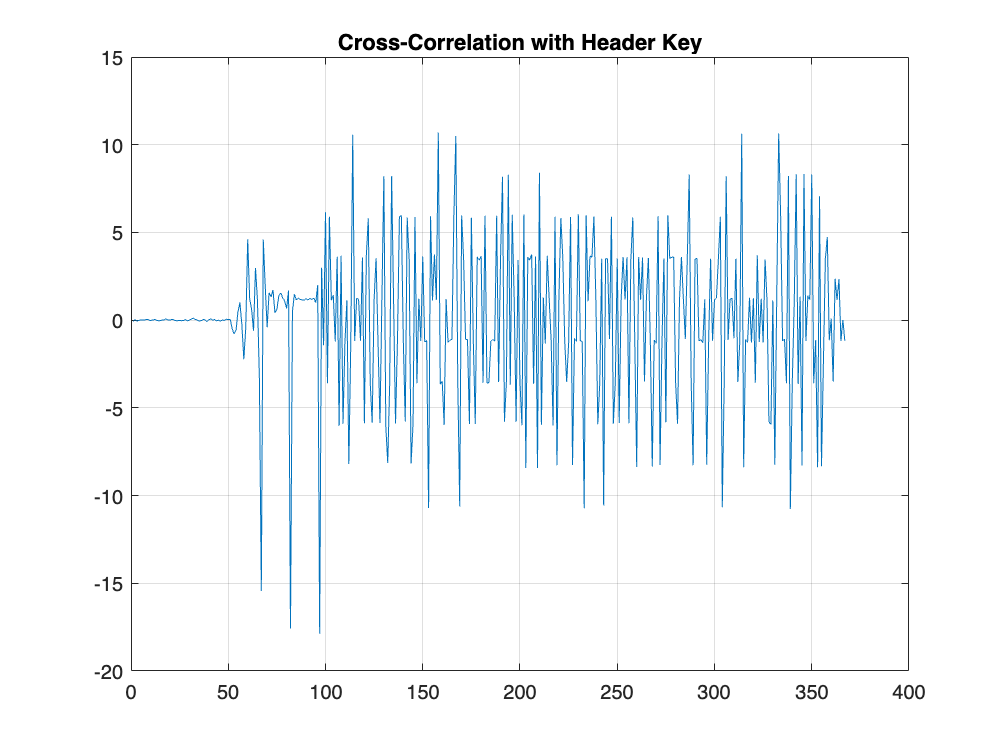

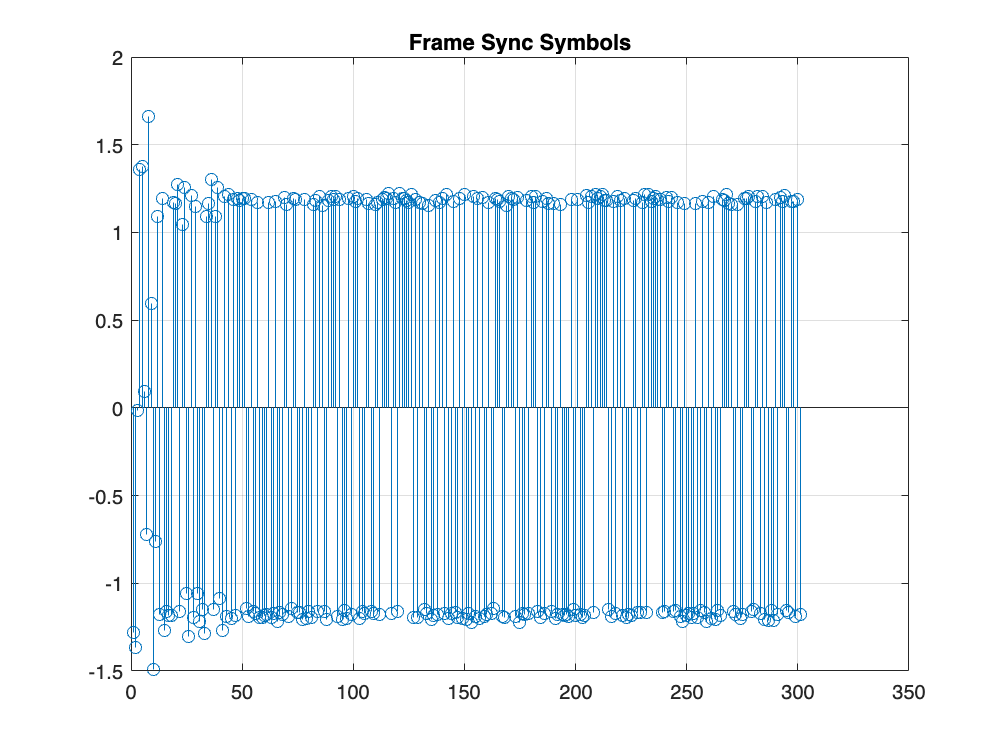

% Frame Sync Algorithm
[aligned_symbols, xc, peak_xcorr] = frame_synchronize(symbs, key, header);
% Frame Sync Plots
frame_sync_plots(xc, aligned_symbols, 1);

## Extract Binary message

% Remove header
aligned_bits = sign(real(aligned_symbols(length(header)+1:end)));

% Map aligned symbols back to bits
aligned_bits(aligned_bits == -1) = 0;

## Calculate BER

% Determine Bit Error Rate
num_bit_errors = sum(aligned_bits(1:length(bits)) ~= bits)

num_bit_errors = 256

BER = 100 * num_bit_errors / length(bits)

BER = 100

## Decode and Display Message

s = string(aligned_bits);
s = strjoin(s);
s = strrep(s, " ", "");
disp(s);

1011110010010000100100011001100010001101100111101000101110001100110111101101111110101100100101101001001010001010100100111001111010001011100101101001000010010001110111111001011010001100110111111001110010010000100100101000111110010011100110101000101110011010


s_len = length(char(s))

s_len = 256

inputString = char(s);
binaryString = inputString(1:end-mod(length(inputString),8));
binaryChunks = reshape(binaryString, 8, []).';
asciiChars = char(bin2dec(binaryChunks)).';
disp(asciiChars);

¼□□□□□□□Þß¬□□□□□□□□□ß□□ß□□□□□□□□


Message should be "Congrats! Simulation is complete"